load('pose.mat');

%Restructuring data:

[p1,p2,poses,subjects]=size(pose)

p1 = 48

p2 = 40

poses = 13

subjects = 68


ks = 5:68;
kacc = zeros(size(ks,2),4); %tracking accuracy wrt k (Bayesian, kNN (k=20))


for k = ks


    pose_trainX = zeros(10*k,p1*p2);
    pose_trainY = zeros(10*k,1);
    pose_testX = zeros(3*k,p1*p2);
    pose_testY = zeros(3*k,1);
    
    for i = 1:k
        for j = 1:10
            temp = pose(:,:,j,i);
            idx = (i-1)*10+j;
            pose_trainX(idx,:) = temp(:); 
            pose_trainY(idx)=i;
        end
        
        for j = 11:13
            temp = pose(:,:,j,i);
            idx = (i-1)*3+(j-10);
            pose_testX(idx,:) = temp(:); 
            pose_testY(idx)=i;
        end
        
    end
    %now pose: rows = image, cols = pixel data
    
    d=5;
    
    
    %[pose_trainX2,V,mu_trainP] = myPCA(pose_trainX,d);
    
    %calibrating PCA using training data:
    train_nP = size(pose_trainX,1);
    colmean = mean(pose_trainX,1);
    pose_trainX_center = pose_trainX-repmat(colmean,[train_nP,1]);
    [U,S,V] = svd(pose_trainX_center);
    
    %applying PCA to training data
    pose_trainX2 = pose_trainX_center*V(:,1:d);
    
    %applying PCA to test data
    test_nP = size(pose_testX,1);
    pose_testX2 = (pose_testX-repmat(mu_trainP,[test_nP,1]))*V(:,1:d); 
    
    
    
    
    
    
    
    %Bayesian classifier:
    
    %Training:
    
    % currently deprecated in case each class has different sizes
    % %restructuring training data for looping:
    % train_xs = zeros(10,d,k); %row = pose, column = pixel, 3d: subject/class
    % for i=1:k
    %     train_xs(:,:,i) = pose_trainX2(pose_trainY==i,:);
    % end
    
    P = repmat(1/k,[k,1]); %applying equal prior probability to each class
    
    %computing sample mean and covariance for each class:
    train_mus = zeros(d,k);
    train_vars = zeros(d,d,k);
    train_Ws = zeros(d,d,k);
    train_ws = zeros(d,k);
    train_omegas = zeros(k,1);
    
    for i=1:k
    
        temp_X = pose_trainX2(pose_trainY==i,:);
        temp_N = size(temp_X,1);
        temp_mu = mean(temp_X,1);
        temp_X_demean = temp_X-repmat(temp_mu,[temp_N,1]); %demeaned face_n to compute covariance matrix
        temp_var = temp_X_demean'*temp_X_demean/temp_N;
        
        train_mus(:,i) = temp_mu;
        train_vars(:,:,i) = temp_var;
       
        temp_invar = inv(temp_var);
        train_Ws(:,:,i) = -0.5*temp_invar;
        train_ws(:,i) = temp_invar*temp_mu';
        train_omegas(i) = -0.5*temp_mu*temp_invar*temp_mu'-0.5*log(det(temp_var))+log(P(i));
    end
    
    
    %computing and storing discriminant function values
    G_pose = zeros(test_nP,k);
    gp = @(x,a) x*train_Ws(:,:,a)*x'+train_ws(:,a)'*x'+train_omegas(a); %defining discriminant function, with x = obs. row, a = class
    
    for i = 1:test_nP
        for j = 1:k
            G_pose(i,j) = gp(pose_testX2(i,:),j);
        end
    end
    
    %making predictions
    G_pose;
    [Z,pose_testY_prB]=max(G_pose,[],2);
    pose_Bcorrect = (pose_testY_prB==pose_testY);
    kacc(k-4,1) = mean(pose_Bcorrect);
    
    %kNN
    K = 20;
    l=1;
    pose_testY_prK = myKNN(pose_trainX2,pose_trainY,pose_testX2,K,l);
    
    pose_Kcorrect = (pose_testY_prK==pose_testY);
    kacc(k-4,2) = mean(pose_Kcorrect);

    %kNN (scaling K)
    K2 = k*2;
    
    pose_testY_prK = myKNN(pose_trainX2,pose_trainY,pose_testX2,K2,l);
    
    pose_K2correct = (pose_testY_prK==pose_testY);
    kacc(k-4,3) = mean(pose_K2correct);
    
    %kNN (L2 norm)
    K3 = 20;
    l=2;
    
    pose_testY_prK = myKNN(pose_trainX2,pose_trainY,pose_testX2,K3,l);
    
    pose_K3correct = (pose_testY_prK==pose_testY);
    kacc(k-4,4) = mean(pose_K3correct);
    

end

clf("reset")

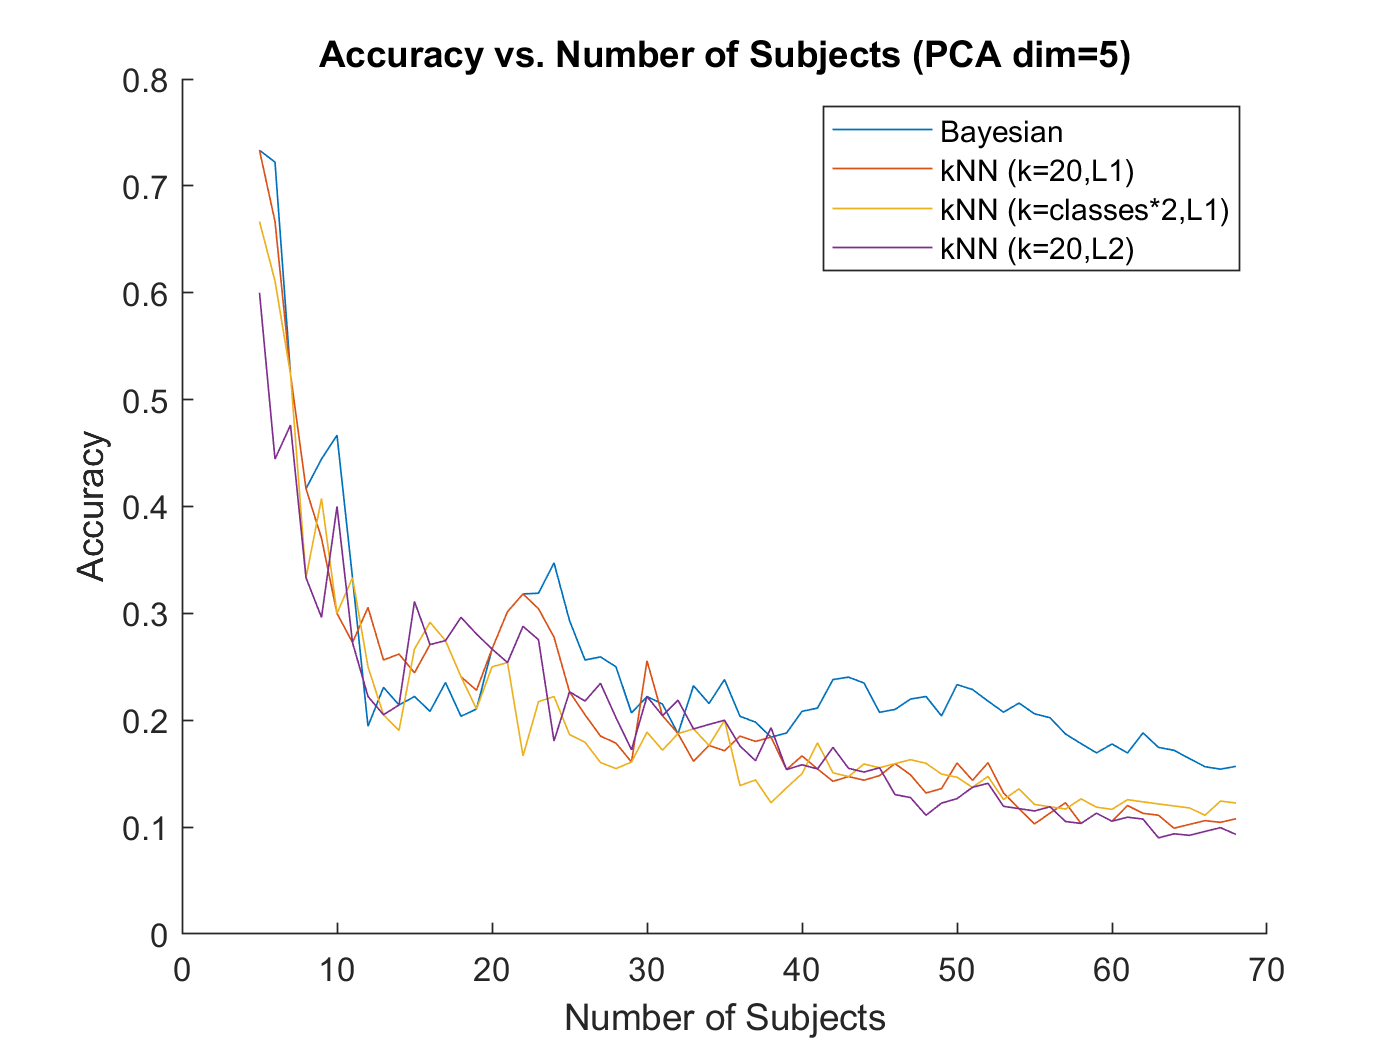

%plotting results
figure(1)
hold on
PL1 = plot(ks,kacc(:,1));
PL2 = plot(ks,kacc(:,2));
PL3 = plot(ks,kacc(:,3));
PL4 = plot(ks,kacc(:,4));
xlabel("Number of Subjects")
ylabel("Accuracy")
title("Accuracy vs. Number of Subjects (PCA dim=5)")
legend([PL1,PL2,PL3,PL4],"Bayesian","kNN (k=20,L1)","kNN (k=classes*2,L1)","kNN (k=20,L2)")
hold off